# Theory (Extension of supersonicShockwave.mlx):

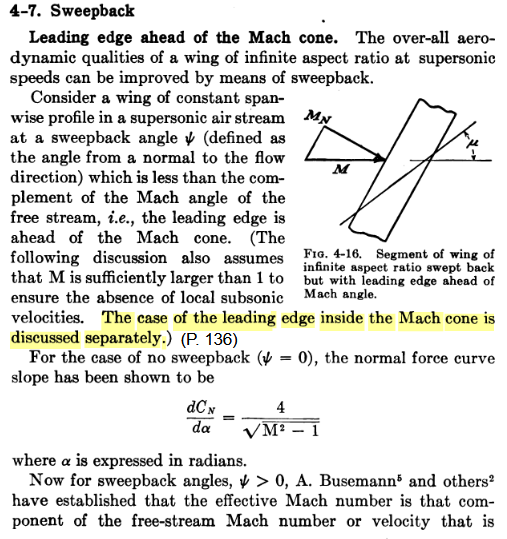

[E. Arthur Bonney - Engineering Supersonic Aerodynamics P. 132]

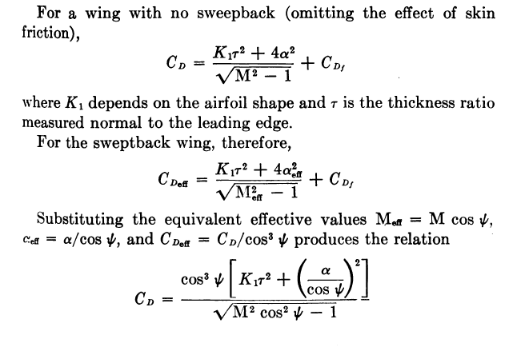

[E. Arthur Bonney - Engineering Supersonic Aerodynamics P. 133]

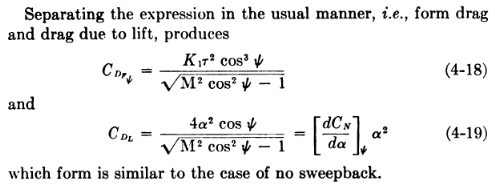

[E. Arthur Bonney - Engineering Supersonic Aerodynamics P. 134]

function C_D = supersonic_sweep_drag(sweepAngle, AoA, Re, Ma)
    % Tau ... thickness ratio "τ"
    %K1 ... constant for cross sectional airfoil shape

    a = 1/8; %General Assumption
    K1 = 2/a;
    Tau = 0.03; %General Assumption

    disp_assumption(sprintf("supersonic_sweep_drag() assumes: \n\t - attached supersonic flow (low AoA, Ma) \n\t - thin flat plate airfoil \n\t - infinite wing span \n - airfoil crossection is currently just generally assumed in K1 and Tau!! \n "));
    
    if AoA > 7
        disp_warning("Warning: Angle of Attack (AoA) is more than 7°, Linear Lift Theory assumes attached flow and low AoA", "supersonic_sweep_drag()");
    end
    C_D_Form = K1*Tau^2*cosd(sweepAngle)^3 / sqrt(Ma^2*cosd(sweepAngle)^2-1);
    C_D_LiftInduced = 4*deg2rad(AoA)^2*cosd(sweepAngle)/sqrt(Ma^2*cosd(sweepAngle)^2-1);
    
    if Re < 10^6
        disp_warning("Warning: Reynolds Number outside of range (Re < 10^6) of figure => Skin Friction is definitely higher)", "supersonic_sweep_drag()");
    end
    C_D_Skin = 0.0045; %worst-case (?)

    C_D = C_D_Form + C_D_LiftInduced + C_D_Skin;
end

# About K1 and Tau Assumptions:

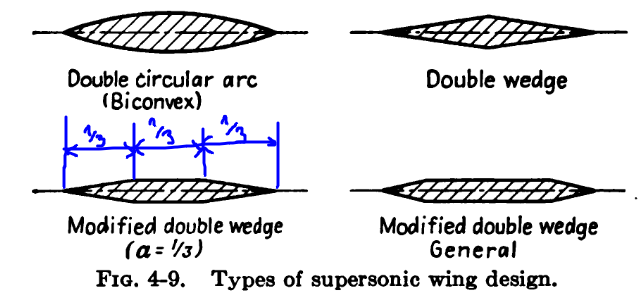

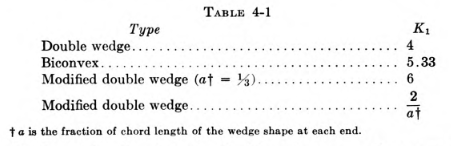

[E. Arthur Bonney - Engineering Supersonic Aerodynamics P. 122]

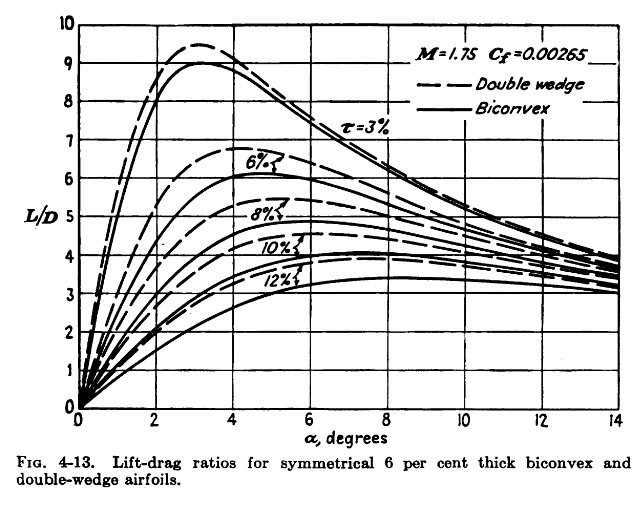

[E. Arthur Bonney - Engineering Supersonic Aerodynamics P. 125]

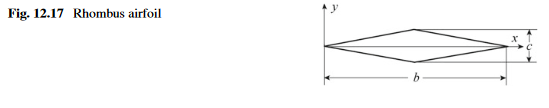

[P. Liu, Aerodynamics, https://doi.org/10.1007/978-981-19-4586-1_12]

Tau = c/b

# About Skin Friction: 

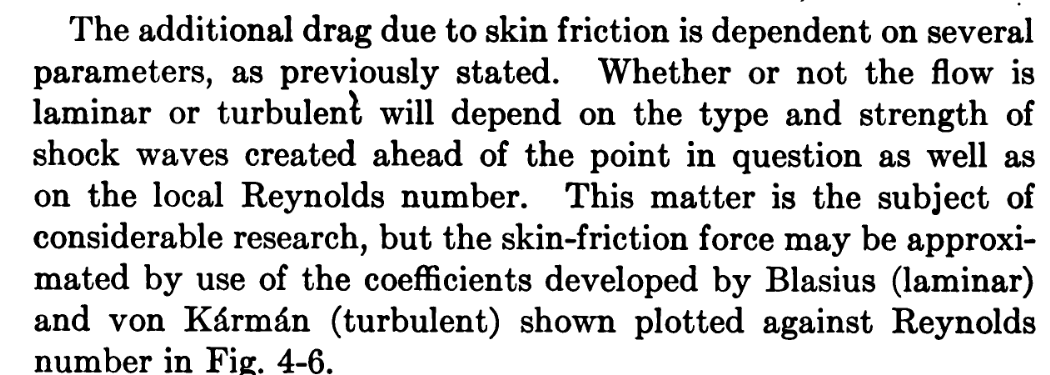

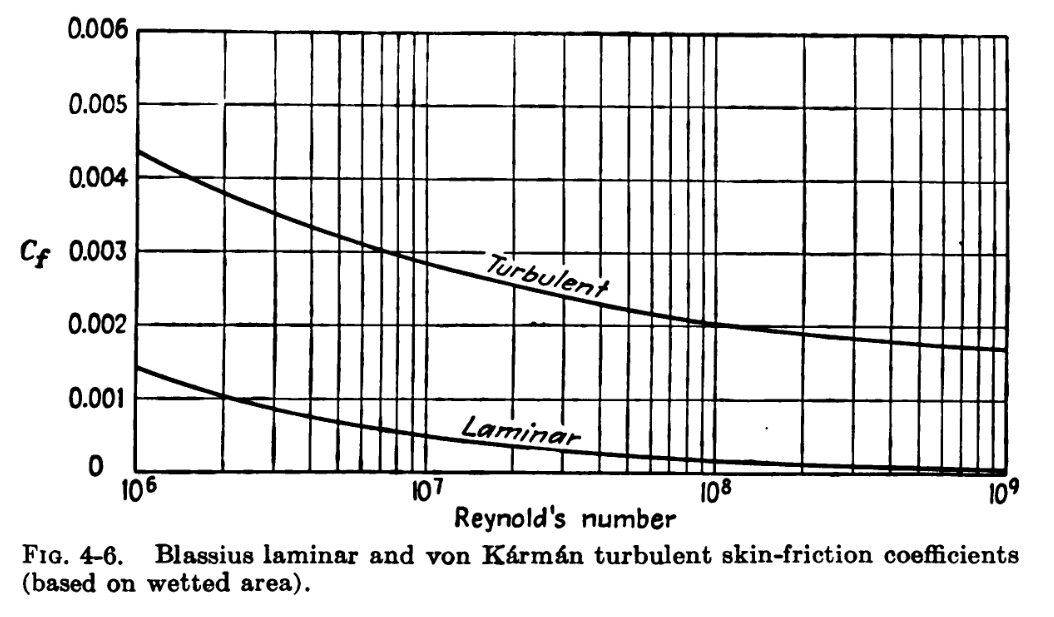

[E. Arthur Bonney - Engineering Supersonic Aerodynamics P. 116f]

Apparant approximation (not checked):

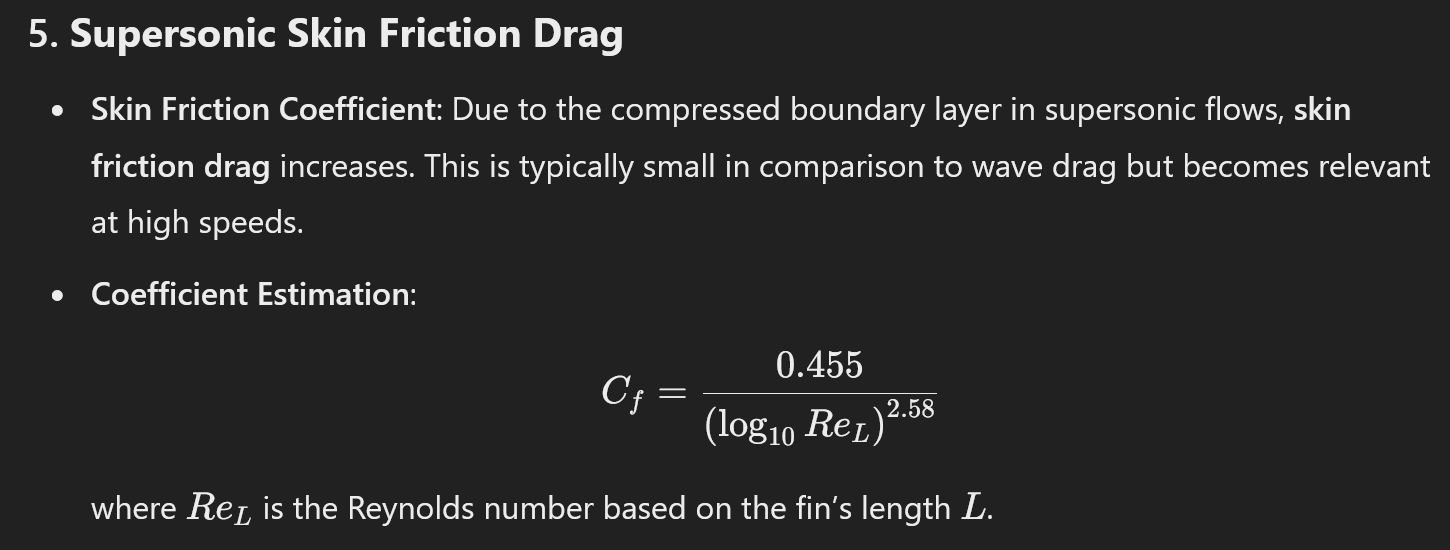

# Limitations:

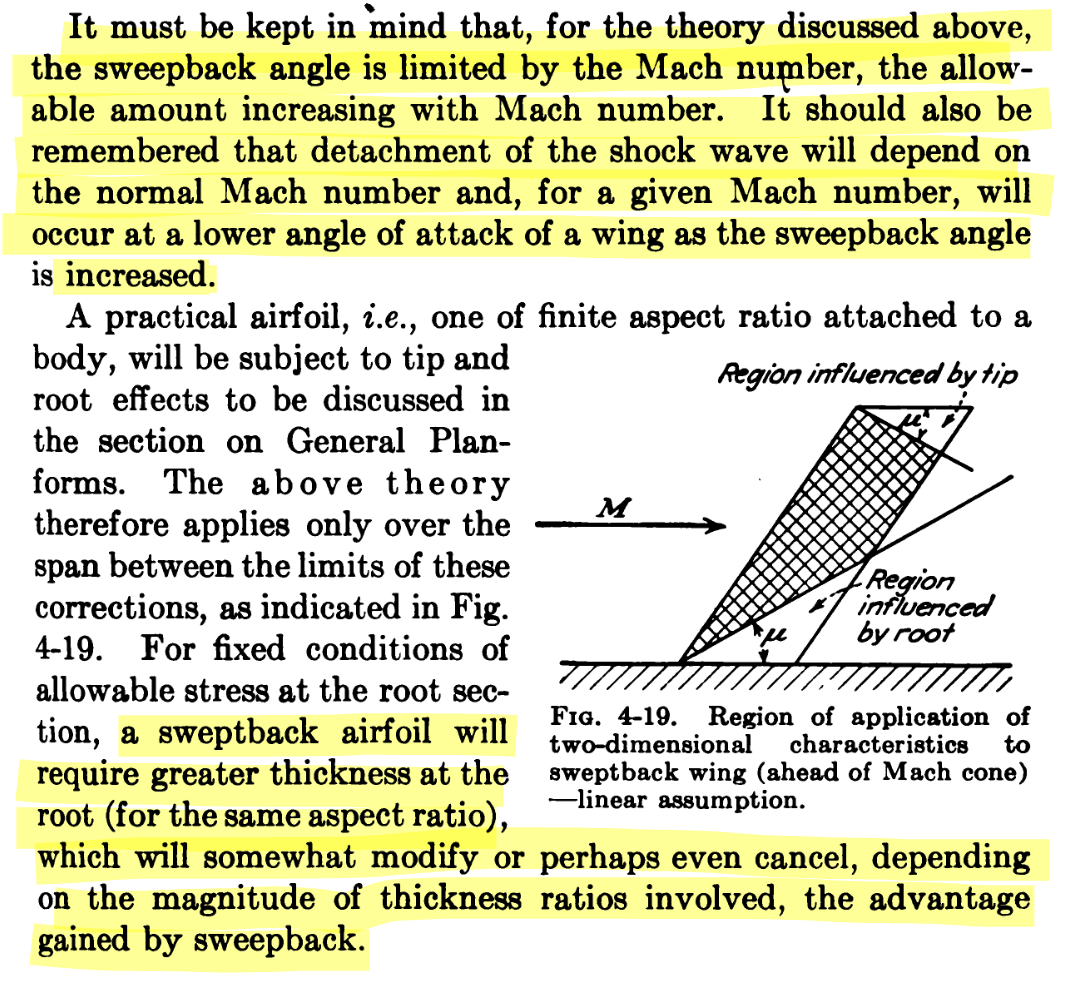

[E. Arthur Bonney - Engineering Supersonic Aerodynamics P. 135]

# Comment:

Aligns with [P. Liu, Aerodynamics, https://doi.org/10.1007/978-981-19-4586-1_12] Chapter 12.5 on Aerodynamic Characterisitcs of Oblique Wings